# Test Time-resolved (TR)

close all
clear variables
clc

## display properties

set(0, 'DefaultAxesFontname', 'Arial CE');
font_size = 16;
set(0, 'DefaultAxesFontsize', font_size);
set(0, 'defaulttextfontname', 'Arial CE');
set(0, 'defaulttextfontsize', font_size);
set(0, 'defaultfigurecolor', 'w');

## BODY

## set the 'nirfasterroot' as current folder

cd(nirfasterroot);

## test TR on standard mesh:

## forward data 2D

mesh = load_mesh('circle2000_86_stnd');

Fixed sources
Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


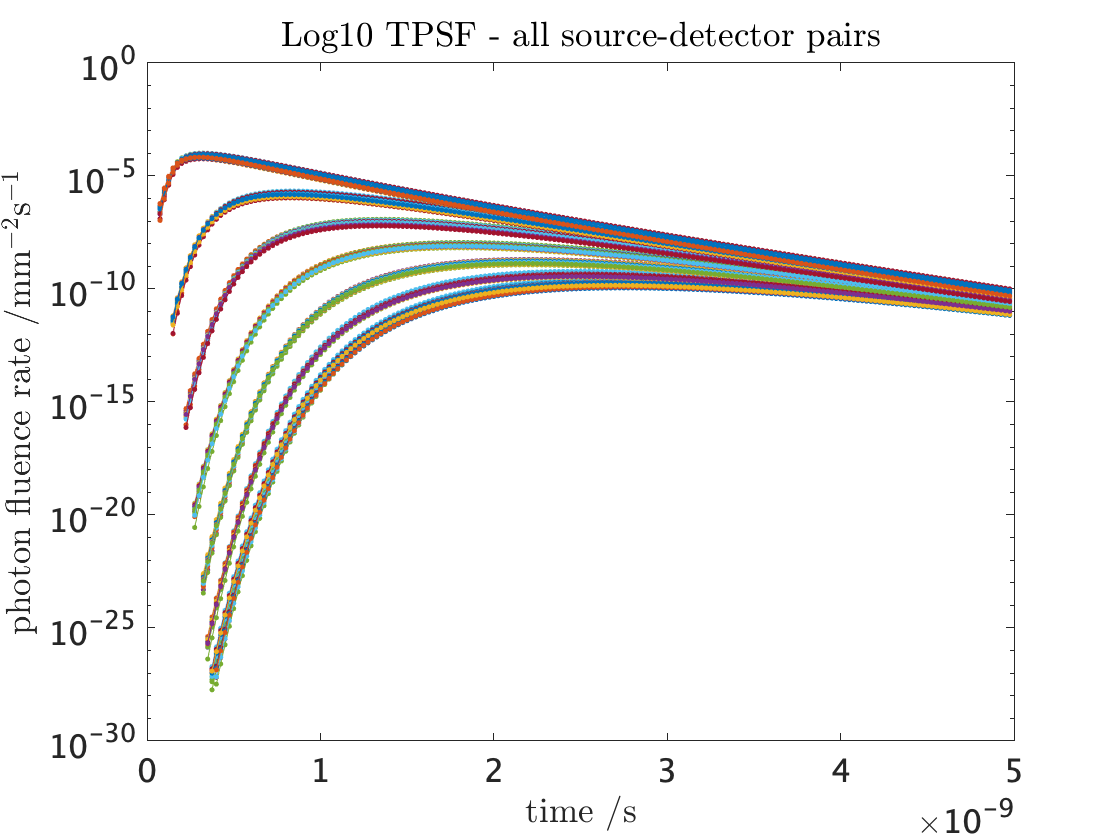


%time-resolved TPSF curve
data_TR = femdata_TR(mesh,5e-9,25e-12);
figure('Name',mesh.name)
semilogy(data_TR.time,abs(data_TR.tpsf)','.-')
title('Log10 TPSF - all source-detector pairs','Interpreter','latex');
xlabel('time /s','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')


% time-resolved moments direct calculation
data_M = femdata_TR_moments(mesh,2);

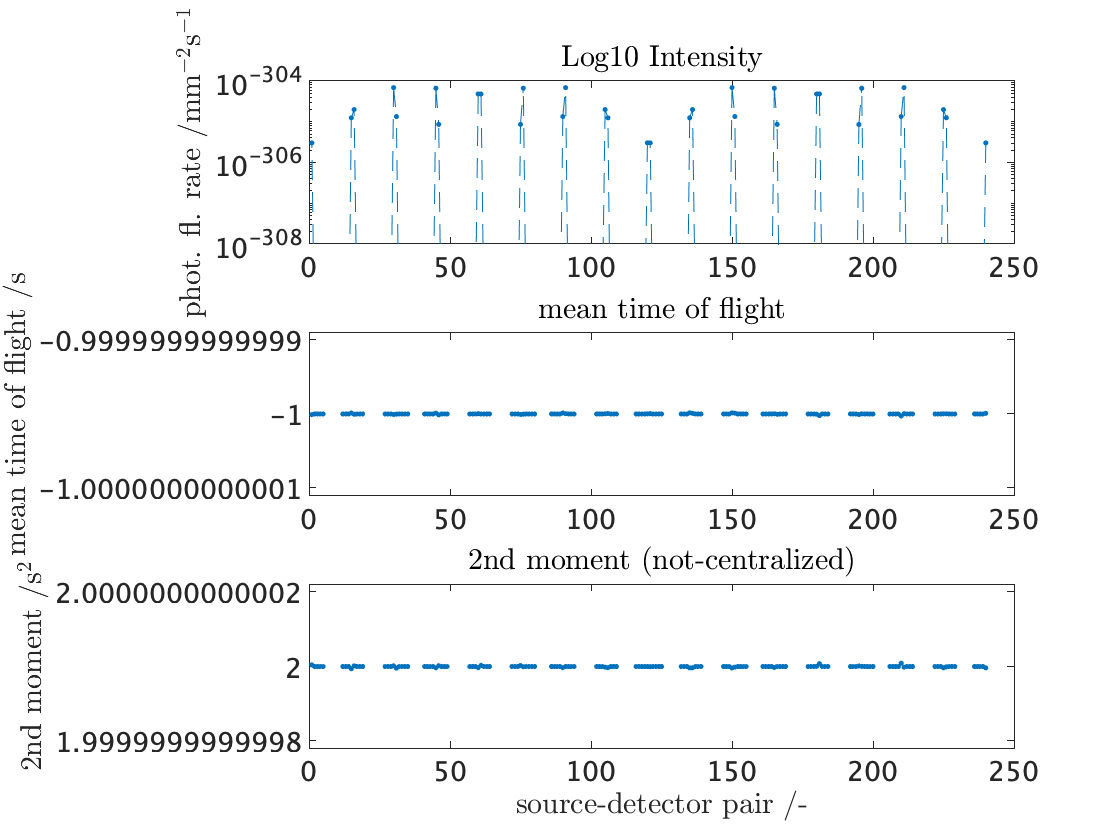

figure('Name',mesh.name)
subplot(3,1,1)
semilogy(abs(data_M.moments(:,1)),'.--')
title('Log10 Intensity','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
subplot(3,1,2)
plot(data_M.moments(:,2),'.--')
title('mean time of flight','Interpreter','latex');
ylabel('mean time of flight /s','Interpreter','latex')
subplot(3,1,3)
plot(data_M.moments(:,3),'.--')
title('2nd moment (not-centralized)','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('2nd moment /s$^{2}$','Interpreter','latex')

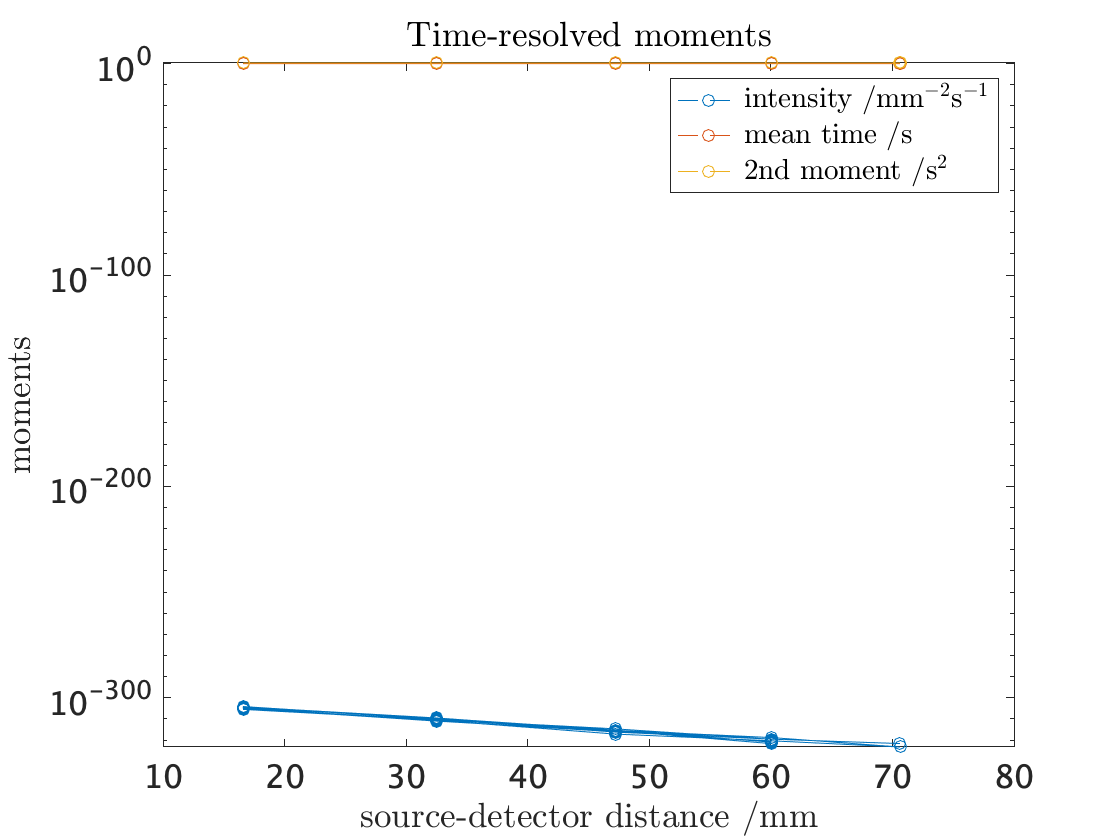


% moments vs distance
%calcuate source-detector distances
sd_distances = sqrt(sum((mesh.meas.coord(mesh.link(:,2),:) - mesh.source.coord(mesh.link(:,1),:)).^2,2));
% plot intensity vs source-detector distances
figure('Name',mesh.name)
semilogy(sd_distances, abs(data_M.moments(:,1:3)) ,'o--')
title('Time-resolved moments','Interpreter','latex');
xlabel('source-detector distance /mm','Interpreter','latex')
ylabel('moments','Interpreter','latex')
legend({'intensity /mm$^{-2}$s$^{-1}$','mean time /s','2nd moment /s$^{2}$'},'Interpreter','latex')

## forward data 3D

mesh = load_mesh('cylinder_stnd');

Sources integration functions loaded
Detectors integration functions loaded


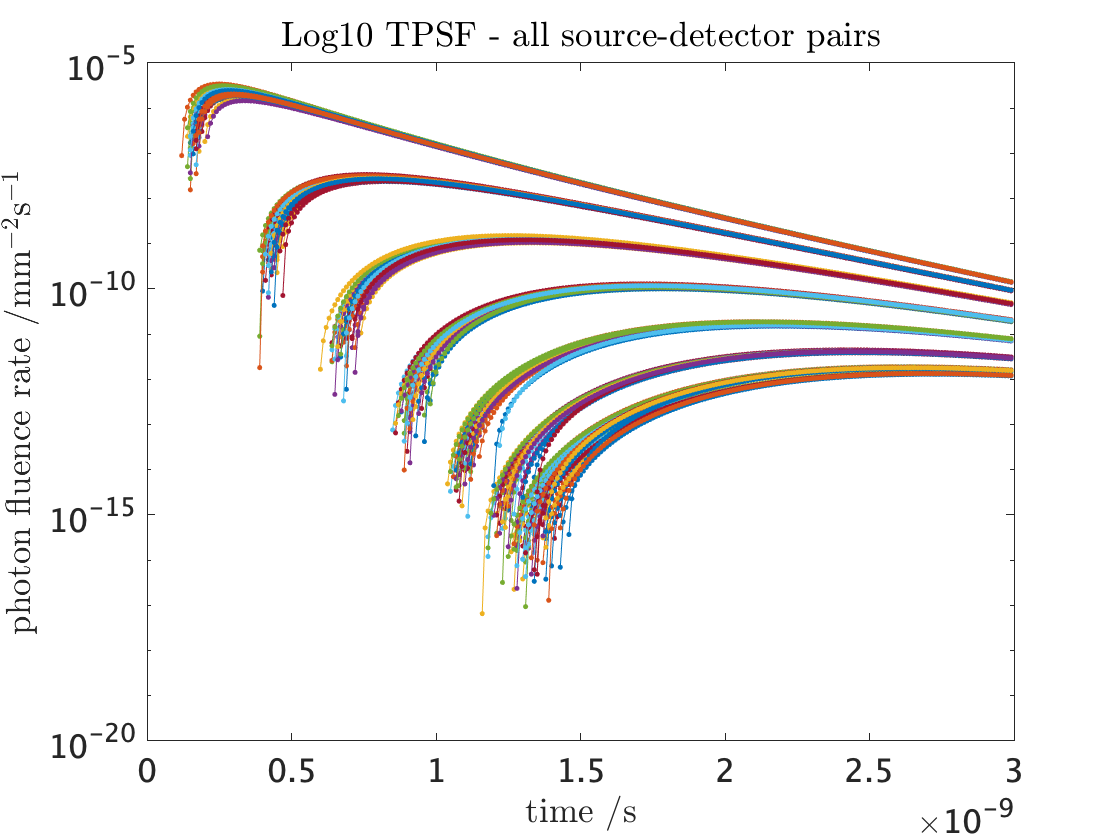


%time-resolved TPSF curve
data_TR = femdata_TR(mesh,3e-9,10e-12);
figure('Name',mesh.name)
semilogy(data_TR.time,abs(data_TR.tpsf)','.-')
title('Log10 TPSF - all source-detector pairs','Interpreter','latex');
xlabel('time /s','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')


% time-resolved moments direct calculation
data_M = femdata_TR_moments(mesh,2);

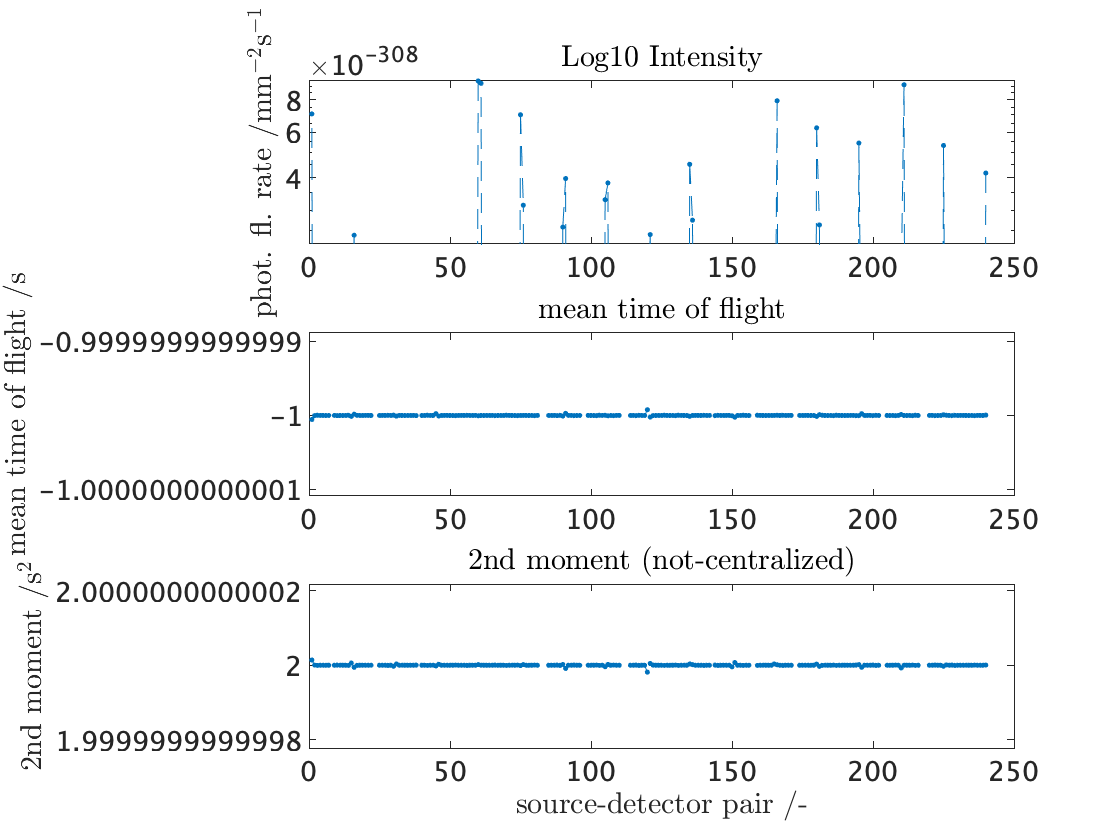

figure('Name',mesh.name)
subplot(3,1,1)
semilogy(abs(data_M.moments(:,1)),'.--')
title('Log10 Intensity','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
subplot(3,1,2)
plot(data_M.moments(:,2),'.--')
title('mean time of flight','Interpreter','latex');
ylabel('mean time of flight /s','Interpreter','latex')
subplot(3,1,3)
plot(data_M.moments(:,3),'.--')
title('2nd moment (not-centralized)','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('2nd moment /s$^{2}$','Interpreter','latex')

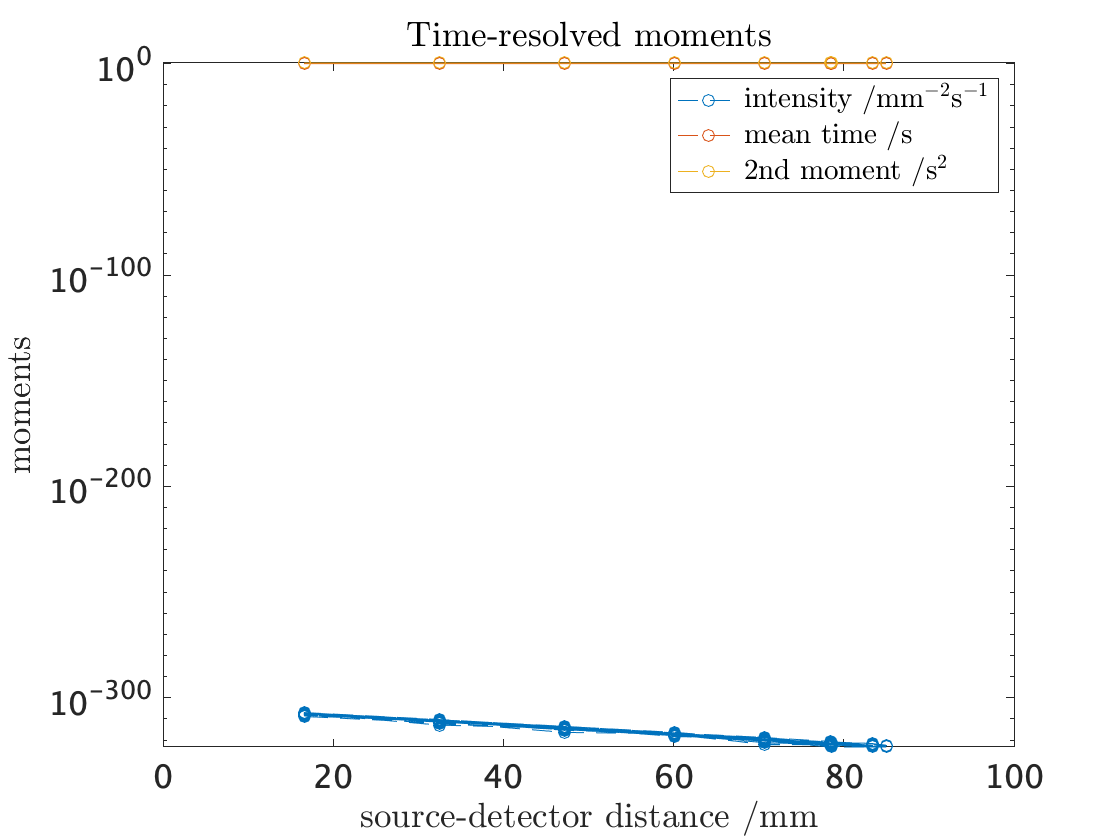


% moments vs distance
%calcuate source-detector distances
sd_distances = sqrt(sum((mesh.meas.coord(mesh.link(:,2),:) - mesh.source.coord(mesh.link(:,1),:)).^2,2));
% plot intensity vs source-detector distances
figure('Name',mesh.name)
semilogy(sd_distances, abs(data_M.moments(:,1:3)),'o--')
title('Time-resolved moments','Interpreter','latex');
xlabel('source-detector distance /mm','Interpreter','latex')
ylabel('moments','Interpreter','latex')
legend({'intensity /mm$^{-2}$s$^{-1}$','mean time /s','2nd moment /s$^{2}$'},'Interpreter','latex')

## test TR on spectral mesh:

## forward data 2D, spectral

mesh = load_mesh('circle2000_86_spec');

Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


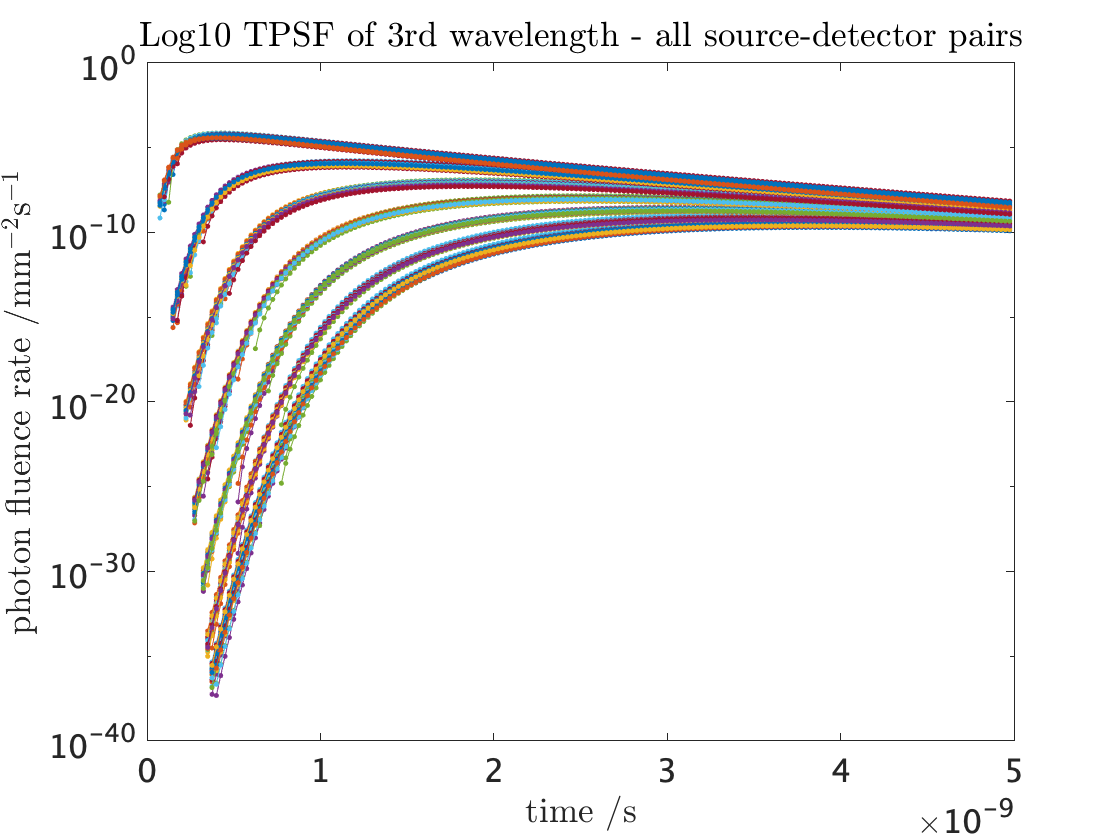


%time-resolved TPSF curve
data_TR = femdata_TR(mesh,5e-9,25e-12);
figure('Name',mesh.name)
semilogy(data_TR.time, abs(squeeze(data_TR.tpsf(:,3,:)))','.-')
title('Log10 TPSF of 3rd wavelength - all source-detector pairs','Interpreter','latex');
xlabel('time /s','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')


% time-resolved moments direct calculation
data_M = femdata_TR_moments(mesh,2);

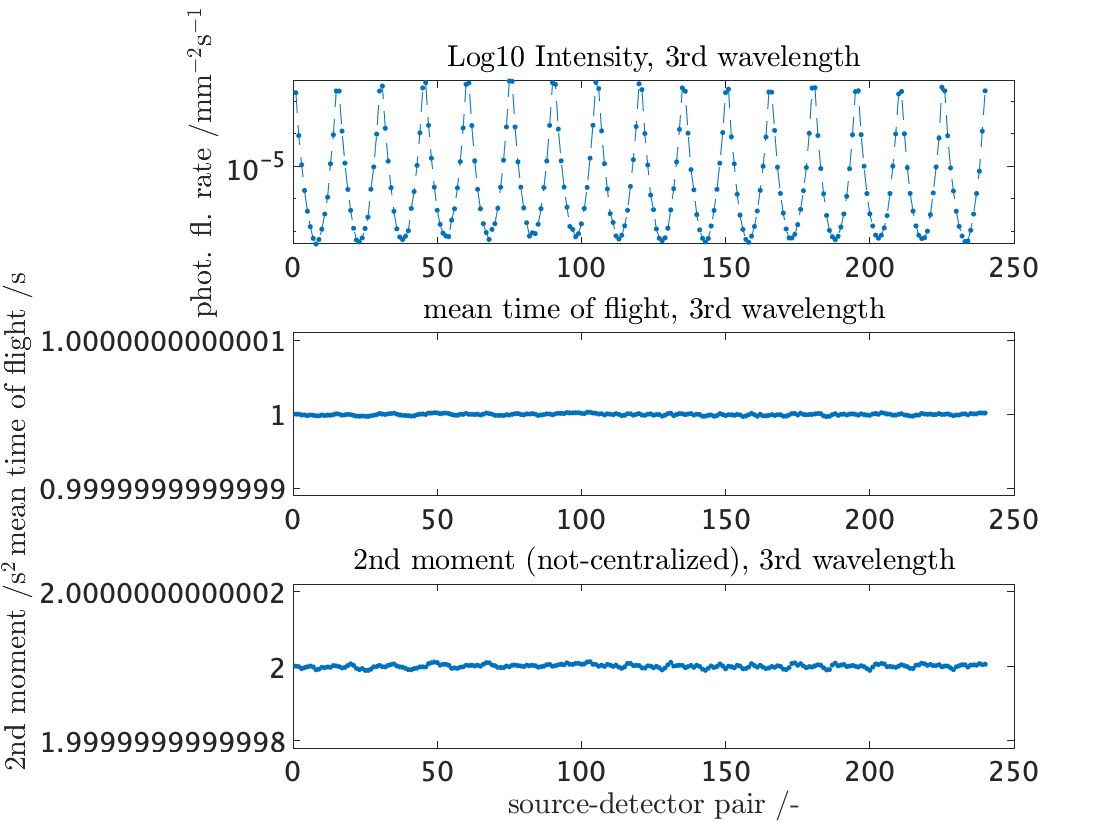

figure('Name',mesh.name)
subplot(3,1,1)
semilogy(abs(squeeze(data_M.moments(:,3,1))),'.--')
title('Log10 Intensity, 3rd wavelength','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
subplot(3,1,2)
plot(squeeze(data_M.moments(:,3,2)),'.--')
title('mean time of flight, 3rd wavelength','Interpreter','latex');
ylabel('mean time of flight /s','Interpreter','latex')
subplot(3,1,3)
plot(squeeze(data_M.moments(:,3,3)),'.--')
title('2nd moment (not-centralized), 3rd wavelength','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('2nd moment /s$^{2}$','Interpreter','latex')

## forward data 3D, spectral

mesh = load_mesh('cylinder_spec');

Fixed sources
Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded



%time-resolved TPSF curve
data_TR = femdata_TR(mesh,3e-9,10e-12);
figure('Name',mesh.name)
semilogy(data_TR.time,abs(squeeze(data_TR.tpsf(:,3,:)))','.-')
title('Log10 TPSF of 3rd wavelength - all source-detector pairs','Interpreter','latex');
xlabel('time /s','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')

% time-resolved moments direct calculation
data_M = femdata_TR_moments(mesh,2);
figure('Name',mesh.name)
subplot(3,1,1)
semilogy(abs(squeeze(data_M.moments(:,3,1))),'.--')
title('Log10 Intensity, 3rd wavelength','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
subplot(3,1,2)
plot(squeeze(data_M.moments(:,3,2)),'.--')
title('mean time of flight, 3rd wavelength','Interpreter','latex');
ylabel('mean time of flight /s','Interpreter','latex')
subplot(3,1,3)
plot(squeeze(data_M.moments(:,3,3)),'.--')
title('2nd moment (not-centralized), 3rd wavelength','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('2nd moment /s$^{2}$','Interpreter','latex')